% Create individual element
freq = 900e6;
vp = physconst('lightspeed');
lambda = vp/freq;
N = 2;
dx = 0.485*lambda;
d = dipole;
d.Length = 0.157;
d.Width = 0.002;

% Orient the antenna element horizontal, parallel, on same axis
d.TiltAxis = 'Y';
d.Tilt = 90;

% Create ULA array
dipole_array = phased.ULA;
dipole_array.Element = d;
dipole_array.ElementSpacing = dx;
dipole_array.NumElements = N;
dipole_array.ArrayAxis = 'x';

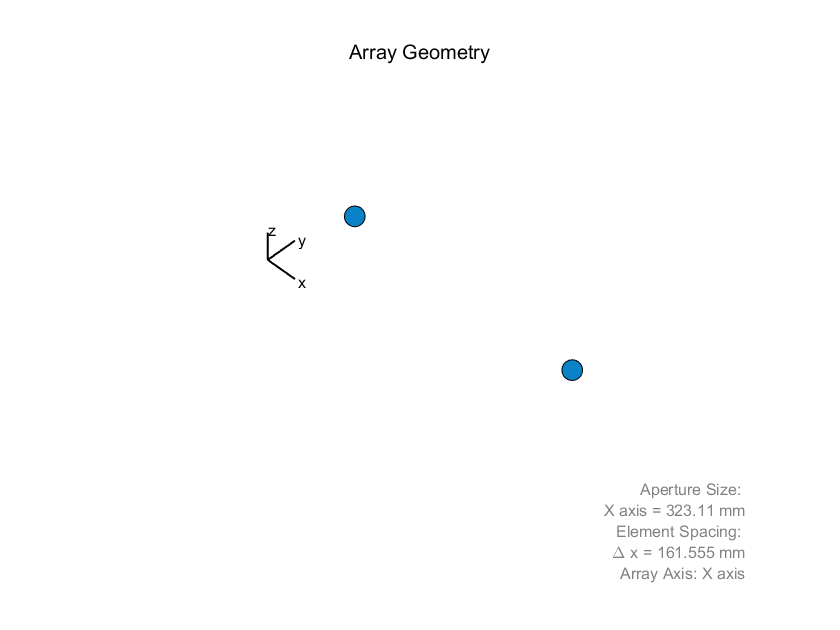

% Display array
viewArray(dipole_array);

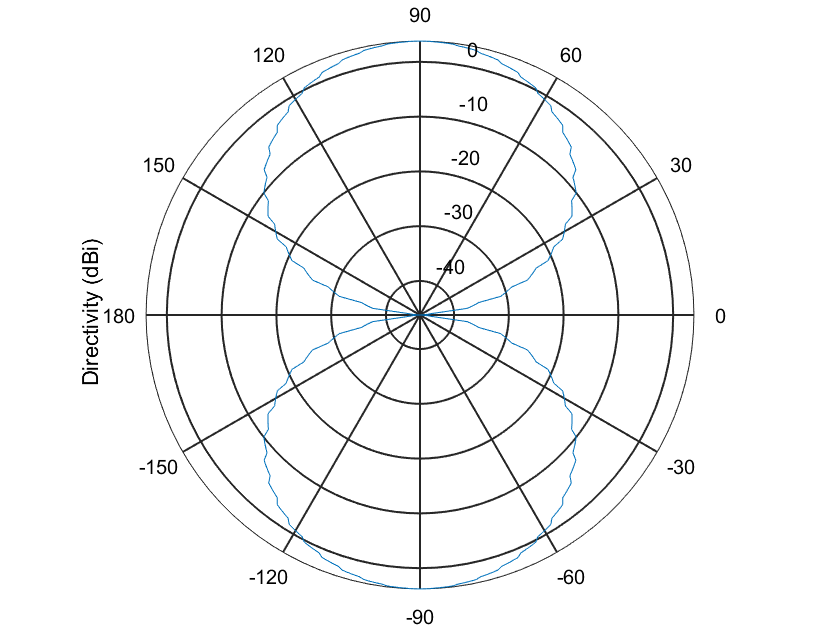

% Display pattern
patternAzimuth(dipole_array, freq);

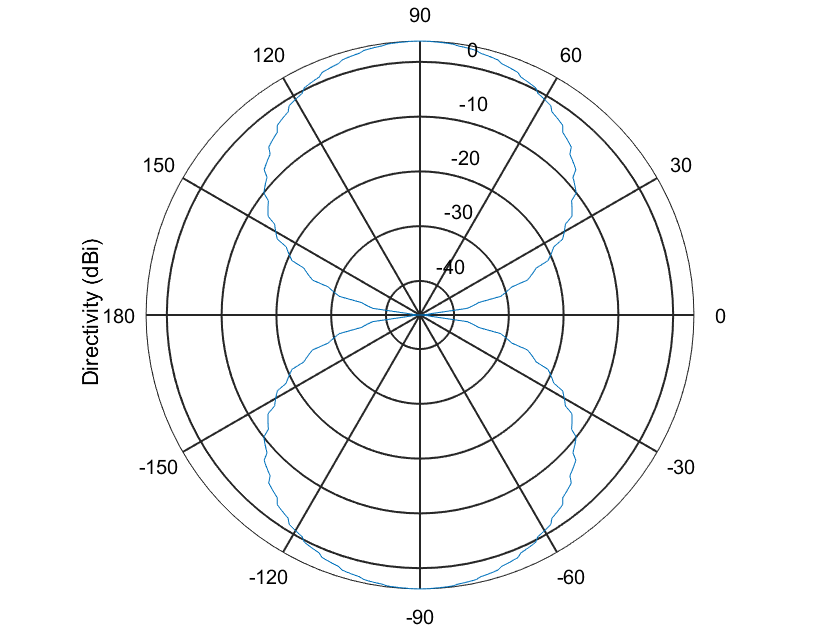

patternElevation(dipole_array, freq);

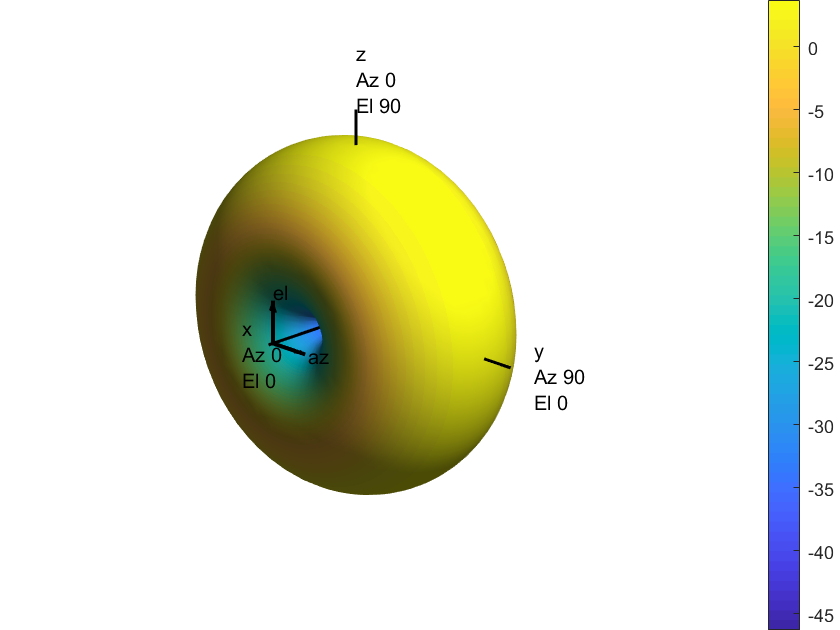

pattern(dipole_array, freq);

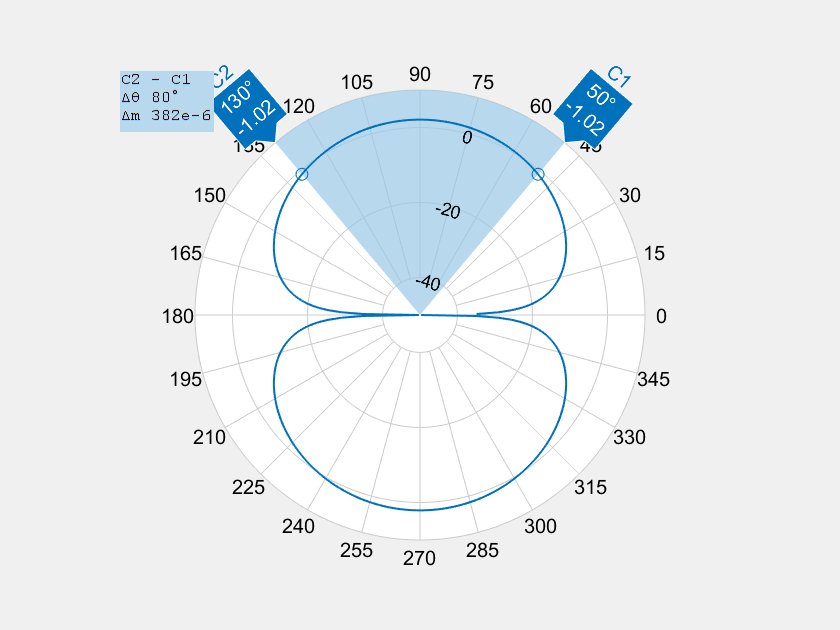

% Plot and calculate beamwidth
beamwidth(d,freq,0,1:1:360);